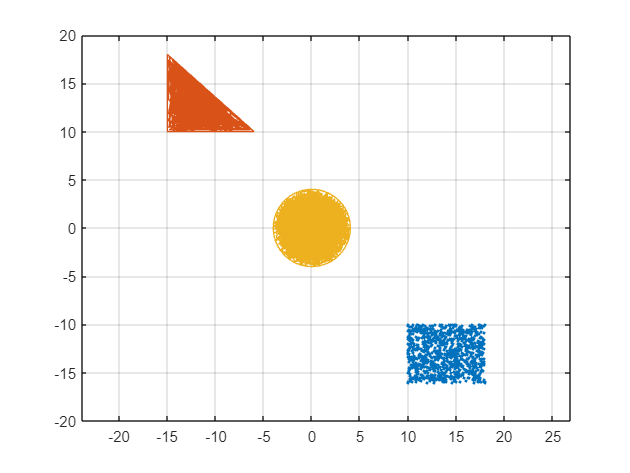


n = 1000;

%Rectangle Obstacle with random points inside;
x1 = [10,18,18,10,10]';           %set the corner of the Xpoints.
y1 = [-10,-10,-16,-16,-10]';      %set the corner of the Ypoints.



x11 = 10+8.*rand(n,1);           %set the random points of X
y11 = -(10+6.*rand(n,1));        %set the random points of Y

X1 = [x1;x11];          %colletive points in the space.
Y1 = [y1;y11];          %collective points in the space.


plot(X1,Y1,'.')        

hold on

%Triangle with the obstacle points in it.
%same the above steps goes for the all other.
x2 = [-15 -6 -15,-15]';
y2 = [18,10,10,18]';

hold on 
x21 = -(6+9.*rand(n,1));
y21 = 10+8*rand(n,1);
p = y21 < 10 - (8/9)*(x21+6);

X2 = [x2;x21(p)];
Y2 = [y2;y21(p)];

plot(X2,Y2)

%Cirlce with random points of obstacle in it.

R3 = 4;


theta = linspace(0,2*pi,100);
x3 = (0+R3*sin(theta))';
y3 = (0+R3*cos(theta))'; 
hold on

% Now create the set of points.
t = 2*pi*rand(n,1);
r = R3*sqrt(rand(n,1));
x31 = 0 + r.*cos(t);
y31 = 0 + r.*sin(t); 

X3= [x3;x31];
Y3= [y3;y31];
plot(X3,Y3)
axis([-20 20 -20 20])
axis equal
grid on;

OX = [X1;X2;X3];
OY = [Y1;Y2;Y3];
cordObstacle = [X Y];

hold off

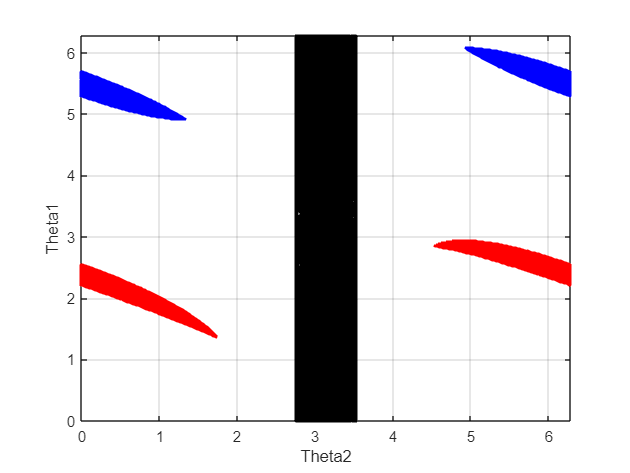

%2=Rlink

l1 = 10;
l2 = 8;

% Define the range of joint angles
theta1_range = linspace(0, 2*pi, 1000);
theta2_range = linspace(0, 2*pi, 1000);


P1x = [];
P1y = [];
P2x = [];
P2y = [];
P3x = [];
P3y = [];
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        [x, y] = forward_kinematics_cspace(theta1_range(i), theta2_range(j),l1,l2);
        if inpolygon(x, y, X1, Y1)
            P1x = [P1x, theta1_range(i)];
            P1y = [P1y, theta2_range(j)];
        elseif inpolygon(x,y,X2,Y2)
            P2x = [P2x, theta1_range(i)];
            P2y = [P2y, theta2_range(j)];
        elseif inpolygon(x,y,X3,Y3)
            P3x = [P3x, theta1_range(i)];
            P3y = [P3y, theta2_range(j)];
        end
    end
end

% Plot the configuration space
plot(P1y,P1x, '.', 'Color', 'blue');
hold on;
plot(P2y,P2x,'.','Color','red')
plot(P3y,P3x,'.','Color','black')
hold off

xlabel('Theta2');
ylabel('Theta1');
axis([0 2*pi 0 2*pi])
grid on 